# Practical on Flux Balance Analysis and its applications

## Author(s): Jeff Orth, Ines Thiele, Ronan Fleming

## INTRODUCTION

In this tutorial, several basic examples of how FBA can be used to analyze constraint-based models, as described in [0], are presented. Many more COBRA methods, including some that are covered in this tutorial, are also presented in the COBRA Toolbox v3.0 paper [ref].  A map of the core model is shown in Figure 1.  Formal reaction name abbreviations are listed in blue text, formal metabolite name abbreviations are listed in purple text. 

## Beginner COBRA methods

Example 0: Calculating growth rates 

Example 1.  Growth on alternate substrates

Example 2.  Production of cofactors and biomass precursors

Example 3.  Alternate optimal solutions

Example 4.  Robustness analysis

Example 5.  Phenotypic phase planes

Example 6.  Simulating gene knockouts

Example 7.  Which genes are essential for which biomass precursor? 

Example 8.  Which non-essential gene knockouts have the greatest effect on the network flexibility?

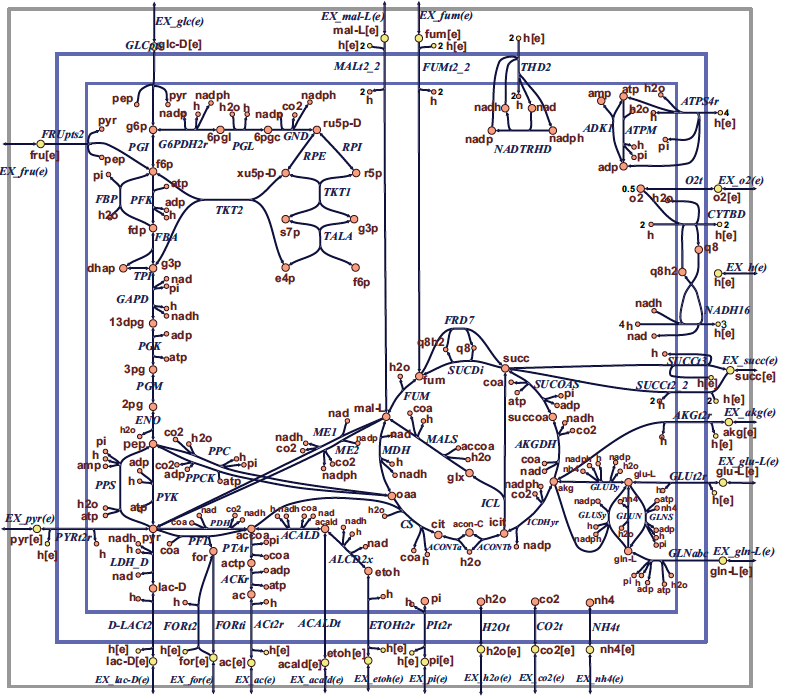

**Figure 1**  Map of the core E. coli metabolic network.  Orange circles represent cytosolic metabolites, yellow circles represent extracellular metabolites, and the blue arrows represent reactions.  Reaction name abbreviations are uppercase and metabolite name abbreviations are lowercase.  These flux maps were drawn using SimPheny and edited for clarity with Adobe Illustrator.

## MATERIALS - EQUIPMENT SETUP

Please ensure that all the required dependencies (e.g. , `git` and `curl`) of The COBRA Toolbox have been properly installed by following the installation guide [here](https://opencobra.github.io/cobratoolbox/stable/installation.html). Please ensure that the COBRA Toolbox has been initialised (tutorial_initialize.mlx) and verify that the pre-packaged LP and QP solvers are functional (tutorial_verify.mlx).

## PROCEDURE

## Load E. coli core model

The most direct way to load a model into The COBRA Toolbox is to use the `readCbModel` function. For example, to load a model from a MAT-file, you can simply use the filename (with or without file extension). 

fileName = 'ecoli_core_model.mat';
if ~exist('modelOri','var')
    modelOri = readCbModel(fileName);
end
%backward compatibility with primer requires relaxation of upper bound on
%ATPM
modelOri = changeRxnBounds(modelOri,'ATPM',1000,'u');
model = modelOri;

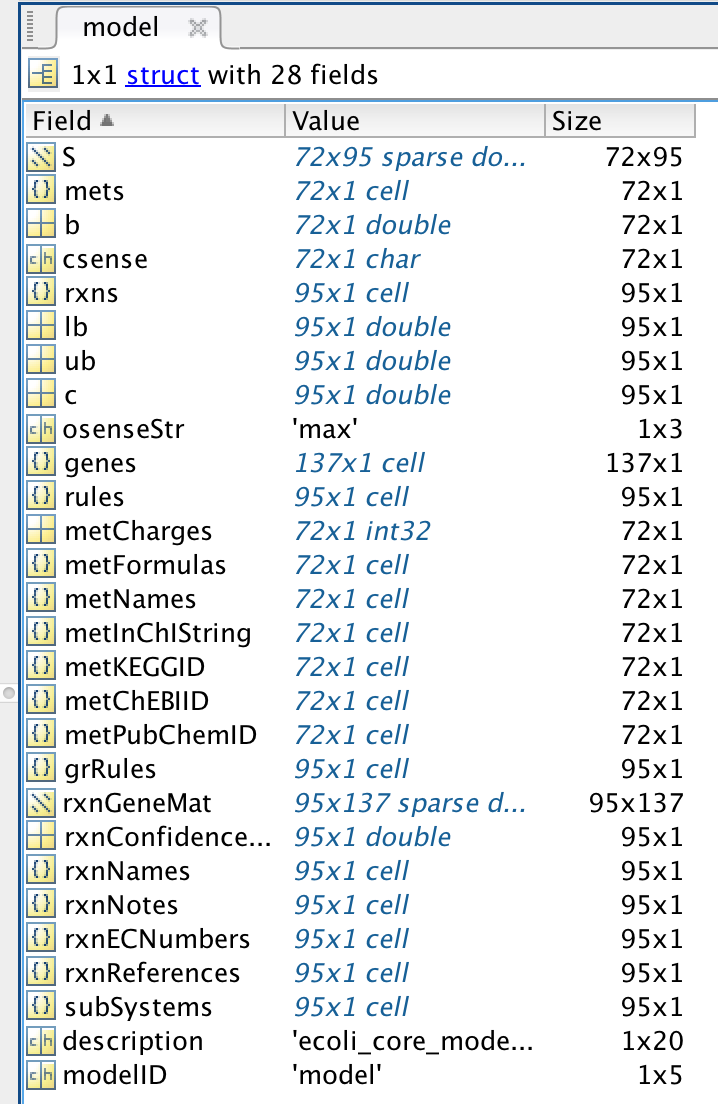

The meaning of each field in a standard model is defined in the [standard COBRA model field definition](https://github.com/opencobra/cobratoolbox/blob/master/docs/source/notes/COBRAModelFields.md).

In general, the following fields should always be present: 

- **S**, the stoichiometric matrix

- **mets**, the identifiers of the metabolites

- **b**, Accumulation (positive) or depletion (negative) of the corresponding metabolites. 0 Indicates no concentration change.

- **csense**, indicator whether the b vector is a lower bound ('G'), upper bound ('L'), or hard constraint 'E' for the metabolites.

- **rxns**, the identifiers of the reactions

- **lb**, the lower bounds of the reactions

- **ub**, the upper bounds of the reactions

- **c**, the linear objective

- **genes**, the list of genes in your model 

- **rules**, the Gene-protein-reaction rules in a computer readable format present in your model.

- **osenseStr**, the objective sense either `'max'` for maximisation or `'min'` for minimisation

## Checking the non-trivial constraints on a model

#### What are the default constraints on the model? 

#### Hint: `printConstraints`

## Calculating growth rates

Growth of E. coli on glucose can be simulated under aerobic conditions.  

#### What is the growth rate of *E. coli *on glucose (uptake rate = 18.5 mmol/gDW/h) under aerobic and anaerobic conditions?  

#### Hint: `changeRxnBounds, optimizeCbModel`

## Display an optimal flux vector on a metabolic map

#### Which reactions/pathways are in use (look at the flux vector and flux map)?

#### Hint: `drawFlux`

outputFormatOK = changeCbMapOutput('matlab');
map=readCbMap('ecoli_core_map');
options.zeroFluxWidth = 0.1;
options.rxnDirMultiplier = 10;
drawFlux(map, model, FBAsolution.v, options);

Unable to resolve the name FBAsolution.v.

#### What reactions of oxidative phosphorylation are active in anaerobic conditions?

#### Hint: `printFluxVector` `drawFlux`

fluxData = FBAsolutionAnaer.v;
nonZeroFlag = 1;
printFluxVector(model, fluxData, nonZeroFlag)

## Example 1.  Growth on alternate substrates

Just as FBA was used to calculate growth rates of E. coli on glucose, it can also be used to simulate growth on other substrates.  The core E. coli model contains exchange reactions for 13 different organic compounds, each of which can be used as the sole carbon source under aerobic conditions. 

#### What is the growth rate of *E. coli *on succinate?

#### Hint: `changeRxnBounds`

model = modelOri;


## Batch prediction of growth rates on different substrates

#### What is the growth rate of E. coli on all 13 substrates in the core model, aerobically and anaerobically?

#### Hint: Use a `for` loop, with `changeRxnBounds` and `optimizeCbModel`

### Example 2.  Production of cofactors and biomass precursors

FBA can also be used to determine the maximum yields of important cofactors and biosynthetic precursors from glucose and other substrates [12].  

#### What is the maximum yield of ATP per mol glucose?

#### Hint: use changeObjective to set the model to maximise the ATP hydrolysis reaction.

#### What is the maximum yield of NADH and NADPH per mol glucose in aerobic and anaerobic conditions?

#### Hint: Check the default constraints on the model before proceeding. Also, use:

model = addReaction(model,'NADH_drain','nadh[c] -> nad[c] + h[c]');

## Sensitivity of a FBA solution

The sensitivity of an FBA solution is indicated by either shadow prices or reduced costs.  A shadow price is a derivative of the objective function with respect to the exchange of a metabolite.  It indicates how much the addition of that metabolite will increase or decrease the objective.  A reduced cost is the derivatives of the objective function with respect to the lower and upper bounds on a reaction, indicating how much relaxation, or tightening, of each bound increases, or decreases, the optimal objective, respectively.  In the COBRA Toolbox, shadow prices and reduced costs are calculated by optimizeCbModel.  The vector of m shadow prices is FBAsolution.dual and the vector of n reduced costs is FBAsolution.rcost.

#### In the E. coli core model, when maximising ATP production, what is the shadow price of cytosolic protons? 

#### Hint: `FBAsolution.y`

#### What is your biochemical interpretation of this change in objective in the current context?

#### Hint: printFluxVector, drawFlux

#### In the E. coli core model, when maximising ATP production, what is the reduced cost of glucose exchange? 

#### Hint: FBAsolution.rcost

#### In the E. coli core model, what is the shadow price of cytosolic protons at (a) maximum NADH yield, and (b) at maximum NADPH yield? 

#### What is your biochemical interpretation of these value in the current context?

#### Hint: `drawFlux`

## Biosynthetic precursor yields

The core E. coli model contains 12 basic biosynthetic precursor compounds that are used to build macromolecules such as nucleic acids and proteins.  The maximum yield of each of these precursor metabolites from glucose can be calculated by adding a demand reaction for each one (a reaction that consumes the compound without producing anything) and setting these as the objectives for FBA.  A yield of 2 moles of a 3-carbon compound from 1 mole of 6-carbin glucose is 100% carbon conversion.

#### What is the maximum yield of 12 basic biosynthetic precursor compounds that are used to build macromolecules such as nucleic acids and proteins? W**hat is the percentage of the carbon atoms in glucose that are converted to the precursor compound (Carbon Conversion) in each case? **

#### Hint: what are the non-zero stoichiometric coefficients in the biomass reaction? See also `model.metFormulas`

## Example 3.  Alternate optimal solutions

The flux distribution calculated by FBA is often not unique.  In many cases, it is possible for a biological system to achieve the same objective value by using alternate pathways, so phenotypically different alternate optimal solutions are possible.   A method that uses FBA to identify alternate optimal solutions is Flux Variability Analysis (FVA)[13].  This is a method that identifies the maximum and minimum possible fluxes through a particular reaction with the objective value constrained to be close to or equal to its optimal value.  Performing FVA on a single reaction using the basic COBRA Toolbox functions is simple.  First, use functions changeRxnBounds, changeObjective, and optimizeCbModel to perform FBA as described in the previous examples.  Get the optimal objective value (FBAsolution.f), and then set both the lower and upper bounds of the objective reaction to exactly this value.  Next, set the reaction of interest as the objective, and use FBA to minimize and maximize this new objective in two separate steps.  This will give the minimum and maximum possible fluxes through this reaction while contributing to the optimal objective value.

#### What reactions vary their optimal flux in the set of alternate optimal solutions to maximum growth of E. coli on succinate? Are there any reactions that are not used in one optimal solution but used in another optimal solution? What are the computational and biochemical aspects to consider when interpreting these alternate optimal solutions?

#### Hint: `fluxVariability`

## Example 4.  Robustness analysis

Another method that uses FBA to analyze network properties is robustness analysis [14].  In this method, the flux through one reaction is varied and the optimal objective value is calculated as a function of this flux.  This reveals how sensitive the objective is to a particular reaction.  There are many insightful combinations of reaction and objective that can be investigated with robustness analysis.  One example is examination of the effects of nutrient uptake on growth rate.  

#### What is the effect of varying glucose uptake rate on growth? At what uptake rates does glucose alone constrain growth?

#### Hint: fix the oxygen uptake rate to 17 mmol gDW-1 hr-1

#### What is the growth rate as a function of oxygen uptake rate with glucose uptake held constant?

#### Hint: fix glucose uptake at 10 mmol gDW-1 hr-1

## Example 5.  Phenotypic phase plane analysis

When performing robustness analysis, one parameter is varied and the network state is calculated.  It is also possible to vary two parameters simultaneously and plot the results as a phenotypic phase plane [15].  These plots can reveal the interactions between two reactions in interesting ways.  

#### Calculate the phenotypic phase plane for maximum growth while varying glucose and oxygen uptake rates? What is the biochemical interpretation of each of the phase planes?

#### Hint: vary uptake rates between 0 and -20 mmol gDW-1 hr-1

## Example 6.  Simulating gene knockouts

Just as growth in different environments can be simulated with FBA, gene knockouts can also be simulated by changing reaction bounds. To simulate the knockout of any gene, its associated reaction or reactions can simply be constrained to not carry flux.  By setting both the upper and lower bounds of a reaction to 0 mmol gDW-1 hr-1, a reaction is essentially knocked out, and is restricted from carrying flux.  The E. coli core model, like many other constraint-based models, contains a list of gene-protein-reaction interactions (GPRs), a list of Boolean rules that dictate which genes are connected with each reaction in the model.  When a reaction is catalyzed by isozymes (two different enzymes that catalyze the same reaction), the associated GPR contains an “or” rule, where either of two or more genes may be knocked out but the reaction will not be constrained. 

#### Which genes are required to be knocked out to eliminate flux through the phosphofructokinase (PFK) reaction?

#### Hint: study the model

#### What is the growth rate of E. coli when the gene b1852 (zwf) is knocked out?

#### Hint: `deleteModelGenes`

#### Knockout every pairwise combination of the 136 genes in the E. coli core model and display the results.

#### Hint: `doubleGeneDeletion`

## Example 7.  Which genes are essential for which biomass precursor? 

Earlier, we saw how to determine essential genes for growth. Here we will repeat the same analysis but instead of optimizing for the biomass production, we will optimize for the synthesis of all biomass precursors individually. 

#### Which genes are essential for synthesis of each biomass precursor?

#### Hint: `addDemandReaction`

#### Which biomass precursors cannot be net synthesised by the E. coli core model? What does this say about the E. coli core model itself?

#### Hint: think about steady state versus mass balance

## Example 8.  Which non-essential gene knockouts have the greatest effect on the network flexibility?

Another question one might be interested in asking is what are the consequences for the network of deleting a non-essential gene? Given an objective, the flux span is the difference between the maximium and minimum alternate optimal flux values for a reaction. A reaction is said to become more flexible if its flux span increases and less flexible if its flux span decreases.

#### What reactions are increased and decreased in flux span in response to deletion of these 6 genes?  `{'b0114', 'b0723', 'b0726', 'b0767', 'b1602', 'b1702'} With reference to a particular example, w`hat is the biochemical interpretation of an increased flux span in response to a gene deletion? 

#### Hint: `fluxVariability`, `hist`

## TIMING

*2 hrs*

## *Acknowledgments*

This tutorial was originally written by Jeff Orth and Ines Thiele for the publication "What is flux balance analysis?"

## REFERENCES

0.    Orth. J., Thiele, I., Palsson, B.O., What is flux balance analysis? Nat Biotechnol. Mar; 28(3): 245–248 (2010).

1.	Becker, S.A. et al. Quantitative prediction of cellular metabolism with constraint-based models: The COBRA Toolbox. Nat. Protocols 2, 727-738 (2007).

2.	Orth, J.D., Fleming, R.M. & Palsson, B.O. in EcoSal - Escherichia coli and Salmonella Cellular and Molecular Biology. (ed. P.D. Karp) (ASM Press, Washington D.C.; 2009).

3.	Covert, M.W., Knight, E.M., Reed, J.L., Herrgard, M.J. & Palsson, B.O. Integrating high-throughput and computational data elucidates bacterial networks. Nature 429, 92-96 (2004).

4.	Segre, D., Vitkup, D. & Church, G.M. Analysis of optimality in natural and perturbed metabolic networks. Proceedings of the National Academy of Sciences of the United States of America 99, 15112-15117 (2002).

5.	Shlomi, T., Berkman, O. & Ruppin, E. Regulatory on/off minimization of metabolic flux changes after genetic perturbations. Proceedings of the National Academy of Sciences of the United States of America 102, 7695-7700 (2005).

6.	Reed, J.L., Famili, I., Thiele, I. & Palsson, B.O. Towards multidimensional genome annotation. Nat Rev Genet 7, 130-141 (2006).

7.	Satish Kumar, V., Dasika, M.S. & Maranas, C.D. Optimization based automated curation of metabolic reconstructions. BMC bioinformatics 8, 212 (2007).

8.	Kumar, V.S. & Maranas, C.D. GrowMatch: an automated method for reconciling in silico/in vivo growth predictions. PLoS Comput Biol 5, e1000308 (2009).

9.	Burgard, A.P., Pharkya, P. & Maranas, C.D. Optknock: a bilevel programming framework for identifying gene knockout strategies for microbial strain optimization. Biotechnology and bioengineering 84, 647-657 (2003).

10.	Patil, K.R., Rocha, I., Forster, J. & Nielsen, J. Evolutionary programming as a platform for in silico metabolic engineering. BMC bioinformatics 6, 308 (2005).

11.	Pharkya, P., Burgard, A.P. & Maranas, C.D. OptStrain: a computational framework for redesign of microbial production systems. Genome research 14, 2367-2376 (2004).

12.	Varma, A. & Palsson, B.O. Metabolic capabilities of Escherichia coli: I. Synthesis of biosynthetic precursors and cofactors. Journal of Theoretical Biology 165, 477-502 (1993).

13.	Mahadevan, R. & Schilling, C.H. The effects of alternate optimal solutions in constraint-based genome-scale metabolic models. Metabolic engineering 5, 264-276 (2003).

14.	Edwards, J.S. & Palsson, B.O. Robustness analysis of the Escherichia coli metabolic network. Biotechnology Progress 16, 927-939 (2000).

15.	Edwards, J.S., Ramakrishna, R. & Palsson, B.O. Characterizing the metabolic phenotype: a phenotype phase plane analysis. Biotechnology and bioengineering 77, 27-36. (2002).

16.	Bell, S.L. & Palsson, B.O. Phenotype phase plane analysis using interior point methods. Computers & Chemical Engineering 29, 481-486 (2005).

17.	Palsson, B.O. Systems biology: properties of reconstructed networks. (Cambridge University Press, New York; 2006).

18.	Barabasi, A.L. & Oltvai, Z.N. Network biology: understanding the cell's functional organization. Nat Rev Genet 5, 101-113 (2004).

19.	Mahadevan, R. & Palsson, B.O. Properties of metabolic networks: structure versus function. Biophysical journal 88, L07-09 (2005).

20.	Price, N.D., Schellenberger, J. & Palsson, B.O. Uniform Sampling of Steady State Flux Spaces: Means to Design Experiments and to Interpret Enzymopathies. Biophysical journal 87, 2172-2186 (2004).

21.	Thiele, I., Price, N.D., Vo, T.D. & Palsson, B.O. Candidate metabolic network states in human mitochondria: Impact of diabetes, ischemia, and diet. The Journal of biological chemistry 280, 11683-11695 (2005).

22. Laurent Heirendt & Sylvain Arreckx, Thomas Pfau, Sebastian N. Mendoza, Anne Richelle, Almut Heinken, Hulda S. Haraldsdottir, Jacek Wachowiak, Sarah M. Keating, Vanja Vlasov, Stefania Magnusdottir, Chiam Yu Ng, German Preciat, Alise Zagare, Siu H.J. Chan, Maike K. Aurich, Catherine M. Clancy, Jennifer Modamio, John T. Sauls, Alberto Noronha, Aarash Bordbar, Benjamin Cousins, Diana C. El Assal, Luis V. Valcarcel, Inigo Apaolaza, Susan Ghaderi, Masoud Ahookhosh, Marouen Ben Guebila, Andrejs Kostromins, Nicolas Sompairac, Hoai M. Le, Ding Ma, Yuekai Sun, Lin Wang, James T. Yurkovich, Miguel A.P. Oliveira, Phan T. Vuong, Lemmer P. El Assal, Inna Kuperstein, Andrei Zinovyev, H. Scott Hinton, William A. Bryant, Francisco J. Aragon Artacho, Francisco J. Planes, Egils Stalidzans, Alejandro Maass, Santosh Vempala, Michael Hucka, Michael A. Saunders, Costas D. Maranas, Nathan E. Lewis, Thomas Sauter, Bernhard Ø. Palsson, Ines Thiele, Ronan M.T. Fleming, **Creation and analysis of biochemical constraint-based models: the COBRA Toolbox v3.0**, Nature Protocols, volume 14, pages 639–702, 2019 [doi.org/10.1038/s41596-018-0098-2](https://doi.org/10.1038/s41596-018-0098-2).